clear
close all
load SIO_PIER_1916_201905.mat

Convert  serial time (days since Jan 1, 0000) to datetime

dtime = datetime(datevec(t));

Display first and last time

formatspec = 't(1) is %.1f, datetime(1) is %s';
display(sprintf(formatspec,t(1),dtime(1)))

t(1) is 700039.0, datetime(1) is 22-Aug-1916


formatspec = 't(end) is %.1f, datetime(end) is %s';
display(sprintf(formatspec,t(end),dtime(end)))

t(end) is 737576.0, datetime(end) is 31-May-2019


[yr,mo,dy] = datevec(dtime);
%yr(1), mo(1), dy(1)
size(Ts)

ans =        37538           1


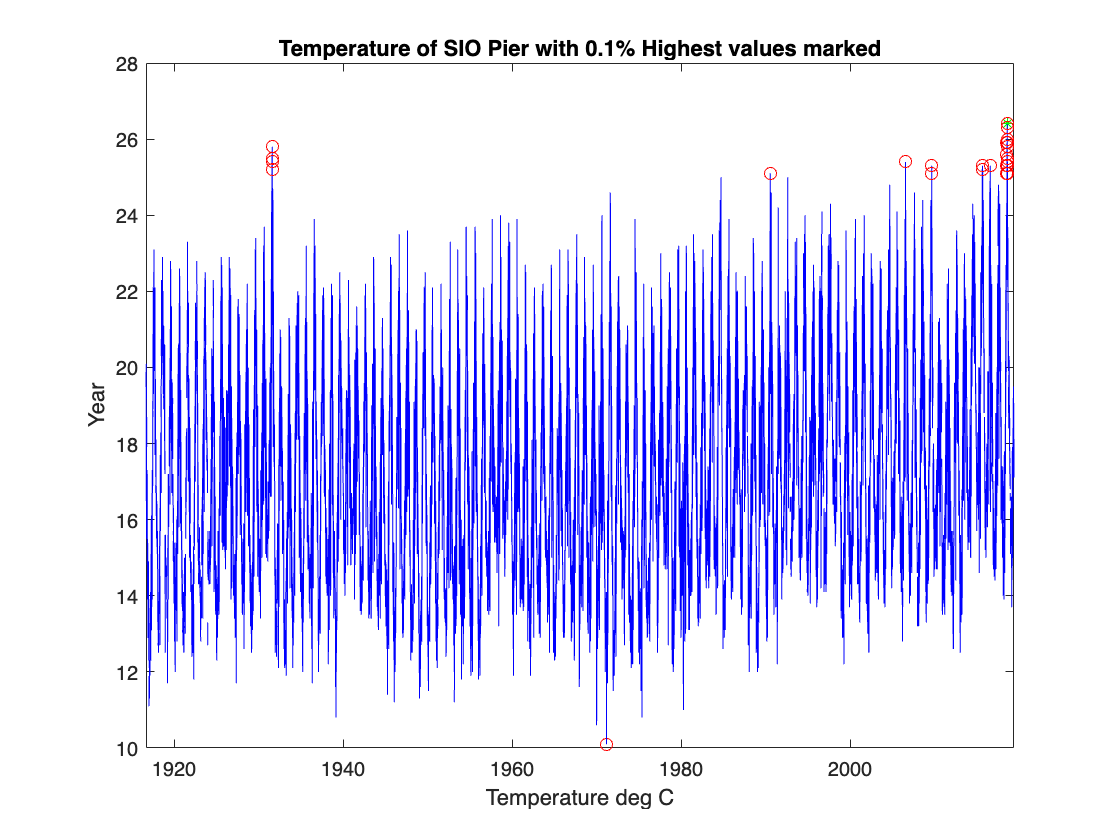

plot(dtime,Ts,'b')
[Tmax,ind_Tmax] = max(Ts,[],'omitnan');
hold on
plot(dtime(ind_Tmax),Tmax,'g*')
[Tmin,ind_Tmin] = min(Ts,[],'omitnan');
plot(dtime(ind_Tmin),Tmin,'ro')
title('Temperature of SIO Pier with 0.1% Highest values marked')
xlabel('Temperature deg C')
ylabel('Year')
plot(dtime,Ts,'b')
hold on
plot(dtime(Ts>25), Ts(Ts>25),'ro')

Q1 Ans : The top 1% values are circled in Red. Mostly, they occur in Summer  period ( July-August-Sept ). They are most frequent in 2018.

ind_July1 = find(mo==7 & dy == 1);
n = length(ind_July1);
Ts_summer = NaN(92,n);
for j = 1:n
    Ts_summer(:,j) = Ts(ind_July1(j):ind_July1(j)+91);
end
yr_summer = yr(ind_July1);
dy_summer = (1:92)';

Alternative reorganization using reshape

Remove Feb 29's, trim to 1917-2018, reshape, pull out JAS

Ts_noleap = Ts((mo~=2 | dy ~= 29) & (yr>=1917 & yr <=2018));
Ts_reshape = reshape(Ts_noleap, 365, 102);
Ts_summer2 = Ts_reshape(182:182+91,:);

quant_9=quantile(Ts_summer2,0.9,2);
quant_5=quantile(Ts_summer2,0.5,2);
quant_1=quantile(Ts_summer2,0.1,2);

Q2 Ans:

plot(dy_summer, quant_1,'g')
hold on
plot(dy_summer, quant_5,'b')
plot(dy_summer, quant_9,'r')
plot(dy_summer,Ts_summer2(:,yr_summer==2018))
ylabel('deg C')
xlabel('days')
title('Top 10% 50% 90% Quantile for summer 1917-2018')
legend('10%','50%','90%','2018')
hold off

Q3 Ans :

histogram(Ts(yr>=1916 & yr<=1935),'Normalization','pdf')
hold on
histogram(Ts(yr>=1999 & yr<=2019),'Normalization','pdf')
hold off
ylabel('probability/deg C')
xlabel('deg C')
legend('First 20 years','Last 20 years')

In recent 20 years, the probability that of high mean temperature has increased.

Q4 Ans : The total days in summer whose average over 1916-2018 exceeds 90 percentile approaches 70 in 2018.

nyrs = length(yr_summer);
MHW = NaN(nyrs,1);
for j=1:nyrs
    MHW(j) = sum(Ts_summer(:,j)>=quant_9);
end
plot(yr_summer,MHW)
xlabel('Years')
ylabel('Days')
title('Number of Days T exceeding 90% Quantile/year ')

yr = 1917:2018;
Ts_year = Ts_reshape(1:365,:);
plot(yr,mean(Ts_year,1,'omitnan'))
ylabel('deg C')
xlabel('Year')
title('Correlation b/w Heat wave with Annual Temperature average')

Q5 Ans : Yes, A marine heat wave is likely to occur if average temperature is higher.

plotyy(yr_summer,MHW,yr,mean(Ts_year,1,'omitnan'))
title('Correlation b/w Heat wave with Annual Temperature average')
ylabel('deg C')
xlabel('Year')
legend('Marine Heat Wave','Temperture Average')

Repeating above procedure for detrended Surface temperatures in another file using code below.

Ans : The number of heat waves do not necessarily increase after detrending.

Ts = detrend(Ts,'omitnan')

Ts =     2.9952
    3.3951
    3.1951
    3.1951
    2.9950
       NaN
    3.5949
    3.3949
    2.4949
   -0.0052
